# 2.5 - Sessão 2 – Oscilador de Onda Rectangular e Secção Biquadrática de Rauch

## 2.1 Objectivos

clear;

## 2.2 Equipamento para Ensaio Laboratorial

R1 = 820;   %(Ohm)
R2 = 3.9e3; %(Ohm)
R3 = 150;   %(Ohm)
R4 = 1.5e3; %(Ohm)
R5 = 1.5e3; %(Ohm)
R6 = 47e3;  %(Ohm)
R8 = 1.2e3; %(Ohm)
R9 = 1.2e3; %(Ohm)
P1 = 100e3; %(Ohm)

C1 = 180e-9; %(F)
C2 = 100e-9; %(F)
C3 = 27e-9;  %(F)
C4 = 27e-9;  %(F)
C5 = 10e-9;  %(F)

Vcc = 12; %(V)

OpAmp = 741;
Timer = 555;

Diode = 333;
U_gamma = 1.4; %(V)

## 2.5 Oscilador

## 2.5.1

NE555 in astable operation (c.f. ne555_ti.pdf p. 11)

As shown in Figure 12, adding a second resistor, RB, to the circuit of Figure 9 and connecting the trigger input to the threshold input causes the timer to self-trigger and run as a multi-vibrator. The capacitor C charges through RA and RB and then discharges through RB only. Therefore, the duty cycle is controlled by the values of RA and RB. 

This astable connection results in capacitor C charging and discharging between the threshold-voltage level (≈ 0.67 × VCC) and the trigger-voltage level (≈ 0.33 × VCC). As in the mono-stable circuit, charge and discharge times (and, therefore, the frequency and duty cycle) are independent of the supply voltage.  

% Determinar experimentalmente
VM_H = Vcc;
VM_L = 0.3; %(V)

% According to datasheet formulae
dutyCycle = 1-R2/(R1+2*R2);
% C2 == 0.1uF = true
f = 1/(0.693*(R1+2*R2)*C1);
fprintf("Duty cycle: %g | frequency: %g Hz \n",dutyCycle,f);

Duty cycle: 0.547564 | frequency: 930.009 Hz 


V_charge = @(t,t0,V0) (VM_H-V0)*(1-exp(-(t-t0)/(C1*(R1+R2))))+V0;
t_charge_ends = @(t0,V0) t0-(R1+R2)*C1*log((1-(2/3))*VM_H/(VM_H-V0));
V_discharge = @(t,t0,V0) V0*exp(-(t-t0)/(C1*R2));
t_discharge_ends = @(t0,V0) t0-R2*C1*log((1/3)*VM_H/V0);

tH = t_charge_ends(0,(1/3)*VM_H);
tL = t_discharge_ends(0,(2/3)*VM_H);
dutyCycle = tH/(tL+tH);
f = 1/(tH+tL);
fprintf("Duty cycle: %g | frequency: %g Hz \n",dutyCycle,f);

Duty cycle: 0.547564 | frequency: 929.811 Hz 


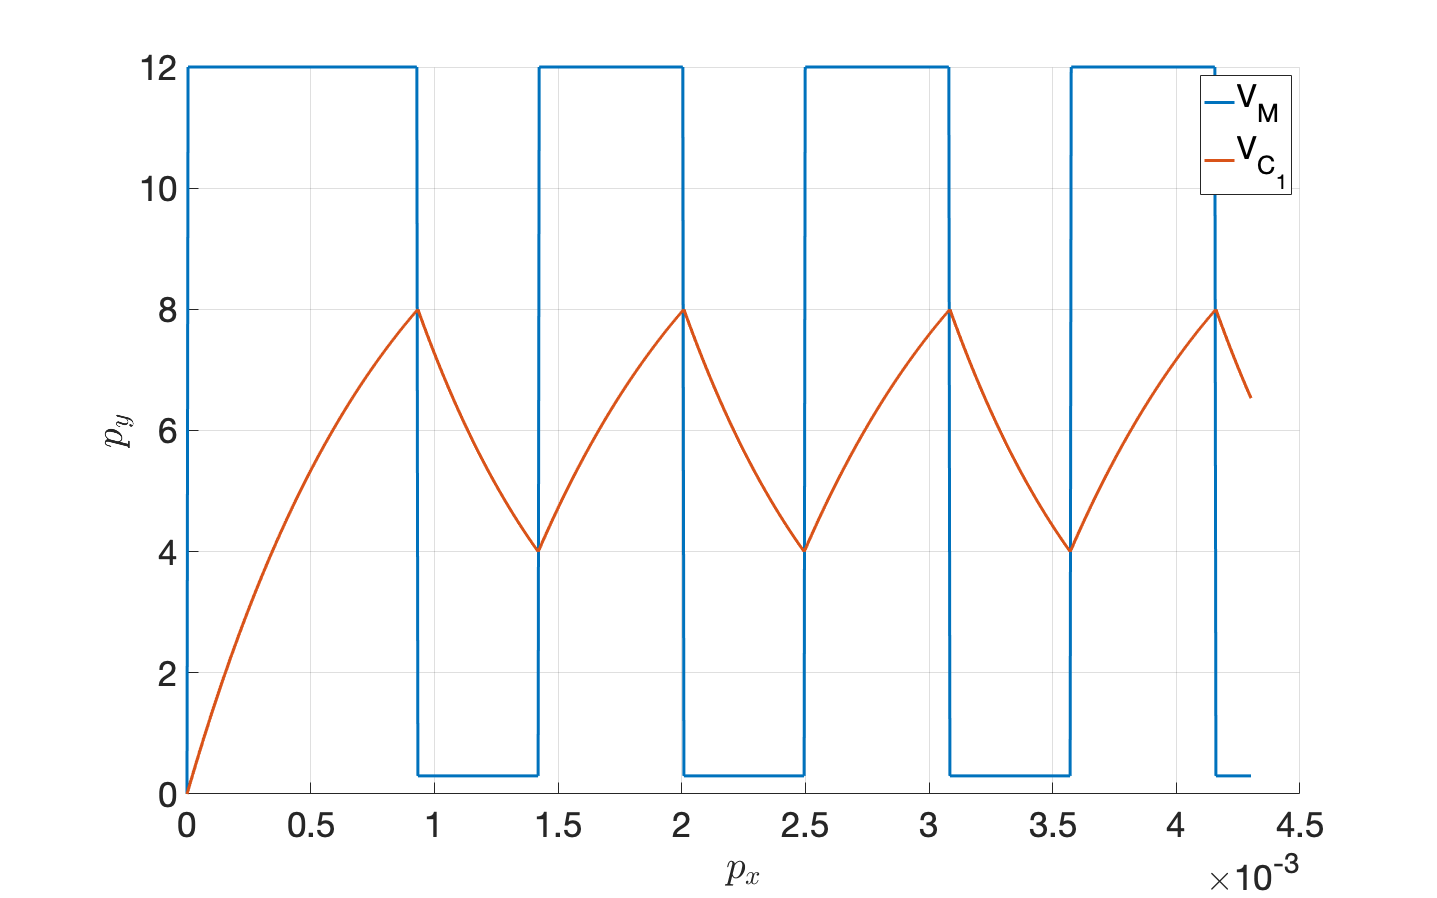

VC1_0 = 0; %(V)
t = [0:4*(1/f)/1e3:4*(1/f)];
VC1 = zeros(size(t));
VM = zeros(size(t));
t0 = 0;
V0 = VC1_0;
VC1(1) = V0;

isCharging = true;
if isCharging 
    t_break = t_charge_ends(t0,V0);
    V_break = V_charge(t_break,t0,V0); 
else
    t_break = t_discharge_ends(t0,V0);
    V_break = V_discharge(t_break,t0,V0); 
end

for i = 2:length(t)
    if t(i) >= t_break
        t0 = t_break;
        V0 = V_break; 
        if ~isCharging 
            t_break = t_charge_ends(t0,V0);
            V_break = V_charge(t_break,t0,V0);
        else
            t_break = t_discharge_ends(t0,V0);
            V_break = V_discharge(t_break,t0,V0); 
        end
        isCharging = ~isCharging;
    end
    if isCharging
        VC1(i) = V_charge(t(i),t0,V0);
        VM(i) = VM_H;
    else
        VC1(i) = V_discharge(t(i),t0,V0);
        VM(i) = VM_L;
    end
end

figure('units','normalized','outerposition',[0 0 1 1]);
hold on;
set(gca,'FontSize',35);
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'on';
%title('Distance from critical point (example)');
p = plot(t,VM);
p.LineWidth = 3;
p = plot(t,VC1);
p.LineWidth = 3;
ylabel('$p_y$','Interpreter','latex');
xlabel('$p_x$','Interpreter','latex');
legend('V_M','V_{C_1}');
hold off;

## 2.5.2

I_max = (VM_H-U_gamma-VM_L)/R3;
I_lim_diode = 100e-3;
fprintf("Maximum current: %g mA < %g mA\n", I_max*1e3,I_lim_diode*1e3);

Maximum current: 68.6667 mA < 100 mA


R3_min = (VM_H-U_gamma-VM_L)/I_lim_diode;
fprintf("Minimum value for R3: %g Ohm",R3_min);

Minimum value for R3: 103 Ohm

## 2.5.3 and beyond

% Fazer experiencias